# ADSI Exam 2019

**Author:** Omar Ali Sheikh, au597954, 201800078

**Date:** 12th June 2019

## Problem 1

clear variables;

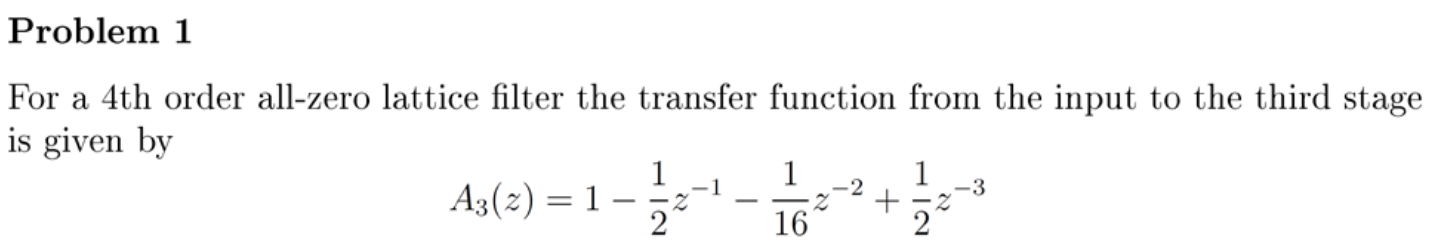

### 1) Determine the reflection coefficients

The recursive algorithm for determining the reflection coefficients works as follows:

- Compute $A_M \left(z\right)=\frac{H\left(z\right)}{h\left\lbrack 0\right\rbrack }$

- Compute $k_M =a_M$ where $a_M$ is the last coefficients of $A_M \left(z\right)$. For example, if $A_M \left(z\right)=1+0\ldotp 06z^{-1} -0\ldotp 42z^{-2} +0\ldotp 5z^{-3}$ then $k_M =0\ldotp 5$

- Compute $B_M \left(z\right)$ by flipping the coefficients of $A_M \left(z\right)$

- Set $m=M$

- Compute $A_{m-1} \left(z\right)=\frac{1}{1-k_m^2 }\left\lbrack A_m \left(z\right)-k_m B_m \left(z\right)\right\rbrack$. The algorithm fails if $k_m =1\to k_m^2 =1$ because of division by zero.

- Compute $k_{m-1} =a_{m-1}$ where $a_{m-1}$ is the last coefficients of $A_{m-1} \left(z\right)$

- Compute $B_{m-1} \left(z\right)$ by flipping the coefficients of $A_{m-1} \left(z\right)$. Alternatively, compute $B_{m-1} \left(z\right)=z^{-m-1} A_{m-1} \left(\frac{1}{z}\right)$

- Set $m=m-1$

- Go to step 5 if $m\not= 0$

- We know that $A_0 \left(z\right)=B_0 \left(z\right)=1$

Step 1:

        
$$A_3 \left(z\right)=1-\frac{1}{2}z^{-1} -\frac{1}{16}z^2 +\frac{1}{2}z^{-3}$$


Step 2:

        
$$k_3 =\frac{1}{2}$$


Step 3:

        
$$B_3 \left(z\right)=\frac{1}{2}-\frac{1}{16}z^{-1} -\frac{1}{2}z^{-2} +z^{-3}$$


Step 5:

        
$$A_2 \left(z\right)=\frac{1}{1-{\left(\frac{1}{2}\right)}^2 }\left\lbrack 1-\frac{1}{2}z^{-1} -\frac{1}{16}z^2 +\frac{1}{2}z^{-3} -\frac{1}{2}\left(\frac{1}{2}-\frac{1}{16}z^{-1} -\frac{1}{2}z^{-2} +z^{-3} \right)\right\rbrack$$


        
$$A_2 \left(z\right)=\frac{1}{0\ldotp 75}\left\lbrack 0\ldotp 75-0\ldotp 4688z^{-1} +0\ldotp 1875z^2 \right\rbrack$$


        
$$A_2 \left(z\right)=1-0\ldotp 6251z^{-1} +0\ldotp 25z^2$$


Step 6:

        
$$k_2 =0\ldotp 25$$


Step 7:

        
$$B_2 \left(z\right)=0\ldotp 25-0\ldotp 6251z^{-1} +z^{-2}$$


Step 5:

        
$$A_{m-1} \left(z\right)=\frac{1}{1-k_m^2 }\left\lbrack A_m \left(z\right)-k_m B_m \left(z\right)\right\rbrack$$


        
$$A_1 \left(z\right)=\frac{1}{1-{\left(0\ldotp 25\right)}^2 }\left\lbrack 1-0\ldotp 6251z^{-1} +0\ldotp 25z^2 -0\ldotp 25\left(0\ldotp 25-0\ldotp 6251z^{-1} +z^{-2} \right)\right\rbrack$$


                 
$$=1\ldotp 0667\left\lbrack 1-0\ldotp 6251z^{-1} +0\ldotp 25z^2 -0\ldotp 0625+0\ldotp 1563z^{-1} -0\ldotp 25z^{-2} \right\rbrack$$


                 
$$=1-0\ldotp 5001z^{-1}$$


Step 6:

        $k_1 =-0\ldotp 5001$  (probably due to some rounding error)

Let us check the results in MATLAB:

b = [1, -1/2, -1/16, 1/2];
tf2latc(b)

ans =    -0.5000
    0.2500
    0.5000


% Recheck the results
k = [-0.5, 0.25, 0.5];
lat2fir(k, 1)

ans =     1.0000   -0.5000   -0.0625    0.5000


The filter coefficients are: $k_1 =-0\ldotp 5,k_2 =0\ldotp 25,k_3 =0\ldotp 5$ 

### 2) Compute a symbolic expression for A4(z)

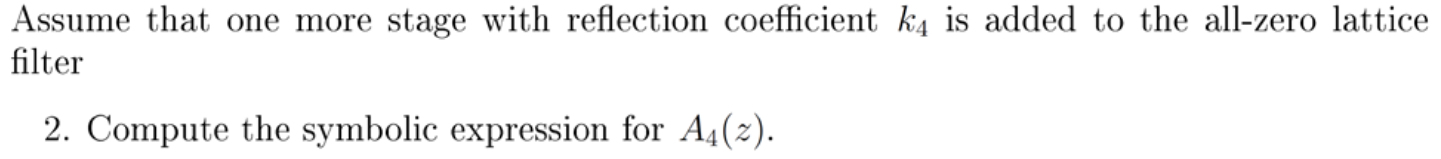

If $m=4$ then we have

        
$$A_3 \left(z\right)=\frac{1}{1-k_4^2 }\left\lbrack A_4 \left(z\right)-k_4 B_4 \left(z\right)\right\rbrack$$


We want to isolate $A_4$:

        
$$A_3 \left(z\right)=\frac{A_4 \left(z\right)}{1-k_4^2 }-\frac{k_4 B_4 \left(z\right)}{1-k_4^2 }$$


        
$$A_3 +\frac{k_4 B_4 \left(z\right)}{1-k_4^2 }=\frac{A_4 \left(z\right)}{1-k_4^2 }$$


        
$$A_4 \left(z\right)=\left(1-k_4^2 \right)\left(A_3 +\frac{k_4 B_4 \left(z\right)}{1-k_4^2 }\right)$$


        
$$A_4 \left(z\right)=\left(\left(1-k_4^2 \right)A_3 +k_4 B_4 \left(z\right)\right)$$


We know that $A_3 \left(z\right)=1-\frac{1}{2}z^{-1} -\frac{1}{16}z^2 +\frac{1}{2}z^{-3}$, our final expression is:

        
$$A_4 \left(z\right)=\left(\left(1-k_4^2 \right)\left(1-\frac{1}{2}z^{-1} -\frac{1}{16}z^2 +\frac{1}{2}z^{-3} \right)+k_4 B_4 \left(z\right)\right)$$


## Problem 2

clear variables;

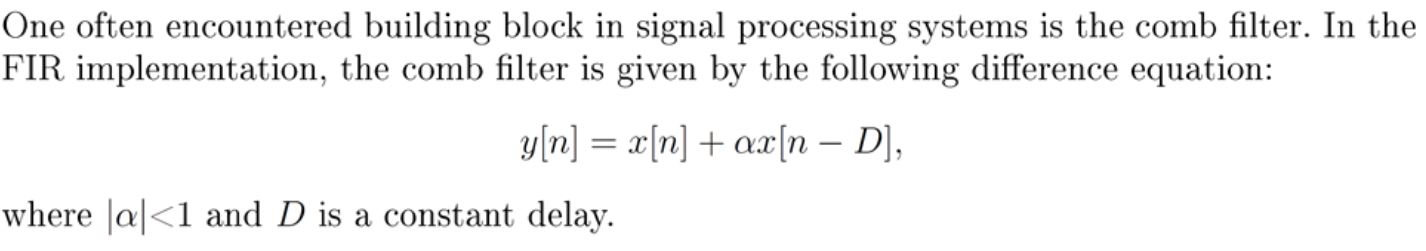

The general transfer function for the comb filter is:

        
$$H\left(z\right)=\frac{Y\left(z\right)}{X\left(z\right)}=1+\alpha z^{-D}$$


The magnitude response for the comb filter:

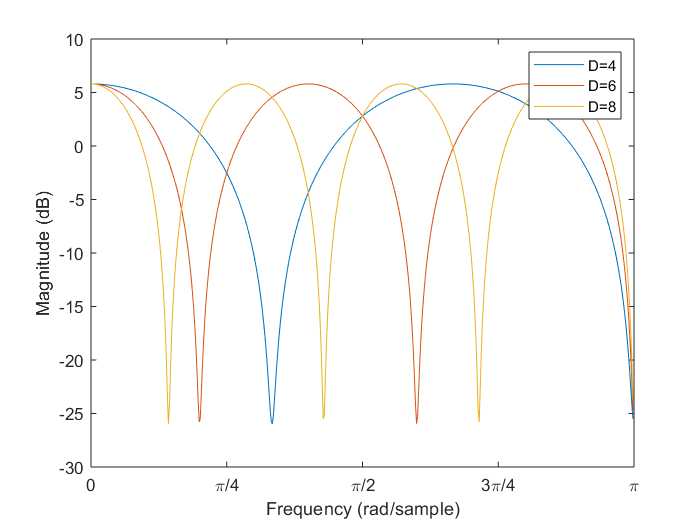

alpha = 0.95;
b4 = [1, 0, 0, alpha];
b6 = [1, 0, 0, 0, 0, alpha];
b8 = [1, 0, 0, 0, 0, 0, 0, alpha];

[H, w] = freqz(b4, 1);
H4 = pow2db(H.*conj(H));
[H, w] = freqz(b6, 1);
H6 = pow2db(H.*conj(H));
[H, w] = freqz(b8, 1);
H8 = pow2db(H.*conj(H));

plot(w, H4, w, H6, w, H8);
legend('D=4', 'D=6', 'D=8')
set(gca,'XTick', 0:pi/4:pi)
set(gca,'XTickLabel', {'0','\pi/4','\pi/2','3\pi/4','\pi'})
xlabel('Frequency (rad/sample)')
ylabel('Magnitude (dB)')
xlim([0, pi]);

The comb filter attenuates certain frequency components of the input signal. It has multiple passbands and stopbands. The comb filter with D=4 attenuates 2 frequency components of the signal. The D=6, attenuates 3 components and finally the D=8 filter attenuates 4 frequency components.

### 2) Compute the autocorrelation function for the comb filter output

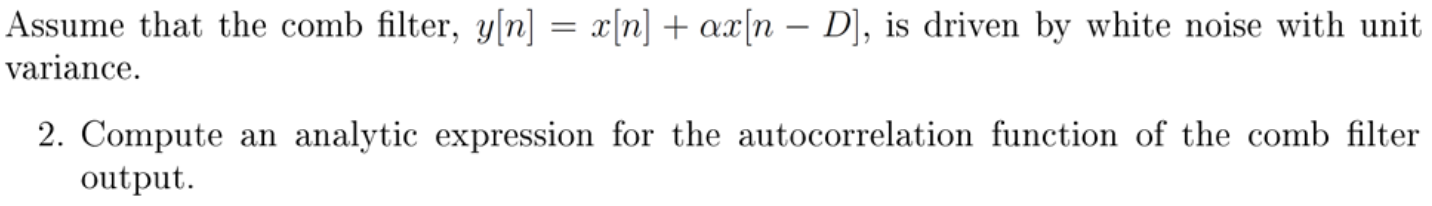

Given $x\left(n\right)~\mathrm{WN}\left(0,1\right)$ we have $r_{\mathrm{xx}} \left(\ell \right)=\sigma_x^2 \delta \left(\ell \right)=1\cdot \delta \left(\ell \right)$

Also, the output of the filter is $y\left(n\right)=x\left(n\right)+\alpha x\left(n-D\right)$

        
$$r_{\mathrm{yy}} \left(\ell \right)=E\left\lbrack y\left(n\right)y\left(n-\ell \right)\right\rbrack$$


                  
$$=E\left\lbrack \left(x\left(n\right)+\alpha x\left(n-D\right)\right)\left(x\left(n-\ell \right)+\alpha x\left(n-\ell -D\right)\right)\right\rbrack$$


                  
$$=E\left\lbrack x\left(n\right)x\left(n-\ell \right)\right\rbrack +E\left\lbrack x\left(n\right)\alpha x\left(n-\ell -D\right)\right\rbrack +E\left\lbrack \alpha x\left(n-D\right)x\left(n-\ell \right)\right\rbrack +E\left\lbrack \alpha x\left(n-D\right)\alpha x\left(n-\ell -D\right)\right\rbrack$$


                  
$$=r_{\mathrm{xx}} \left(\ell \right)+\alpha r_{\mathrm{xx}} \left(\ell -D\right)+\alpha r_{\mathrm{xx}} \left(\ell +D\right)+\alpha^2 r_{\mathrm{xx}} \left(\ell \right)$$


                  
$$=\delta \left(\ell \right)+\alpha \delta \left(\ell -D\right)+\alpha \delta \left(\ell +D\right)+\alpha^2 \delta \left(\ell \right)$$


### 3) Is the comb filter invertible?

A filter $H\left(z\right)=\frac{B\left(z\right)}{A\left(z\right)}$ is said to be stable and causal if all the poles of $H\left(z\right)$ are inside the unit circle.

If the inverse filter $H_{\mathrm{inv}} \left(z\right)=\frac{A\left(z\right)}{B\left(z\right)}$ has to be stable and causal, then all the poles of $H_{\textrm{inv}} \left(z\right)$ must be inside the unit circle or equivalently all zeros of $H\left(z\right)$ must be inside the unit circle.

In practice, we say that a system is only invertible if its zeros and poles are inside the unit circle (minimum-phase system).

Finding zeros of the system functions, we observe that the zeros are inside the unit circle for $\alpha =0\ldotp 98$ but very close to being on the unit circle. However, if $\alpha =1$ then the zeros will be on the unit circle which means that the filter will remove certain frequency components. The problem is that the inverse filter cannot reconstruct the original signal because of deleted information from the signal i.e., the missing frequency component cannot be recovered. 

abs(roots(b4))

ans =     0.9830
    0.9830
    0.9830


abs(roots(b6))

ans =     0.9898
    0.9898
    0.9898
    0.9898
    0.9898


abs(roots(b8))

ans =     0.9927
    0.9927
    0.9927
    0.9927
    0.9927
    0.9927
    0.9927


## Problem 3

clear variables;

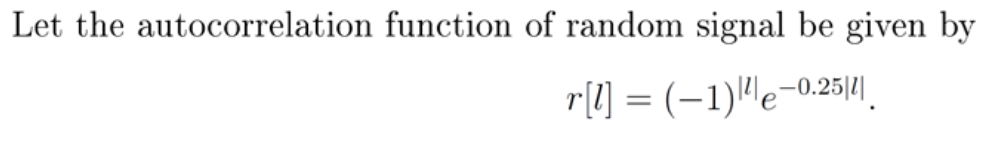

p = 10;
ell = 0:p-1;
r_xx = ((-1).^abs(ell)).*exp(-0.25.*abs(ell))

r_xx =     1.0000   -0.7788    0.6065   -0.4724    0.3679   -0.2865    0.2231   -0.1738    0.1353   -0.1054


### 1) Compute and plot the spectrum assuming an MA(2) model

The PSD for an MA(q) process can be computed using Eq. (13.119):

        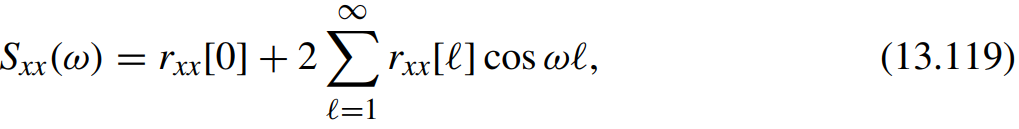

Compute and plot the PSD in MATLAB:

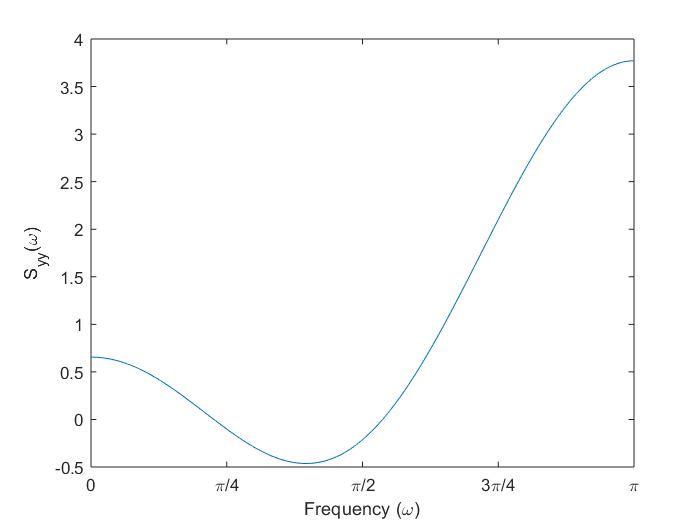

w=0:0.001:pi;

S = r_xx(1);
for l = 2:3
    S = S + 2 * r_xx(l)*cos(w*(l-1));
end

plot(w, S);
xlabel('Frequency (\omega)');
ylabel('S_{yy}(\omega)');
set(gca,'XTick',0:pi/4:pi) 
set(gca,'XTickLabel',{'0', '\pi/4', '\pi/2', '3\pi/4', '\pi'})
xlim([0, pi])

### 2) Compute and plot the spectrum assuming Pisarenko model

The Pisarenko method can be used to recover the sinusoidal frequencies of a corrupted signal $x\left(n\right)$ given two assumptions:

- The signal $x\left(n\right)$ consists of $p$ sinusoids that has been corrupted by white noise.

- The autocorrelation matrix of size $\left(p+1\right)\times \left(p+1\right)$ is known or can be estimated from data

The Pisarenko method consists of the following steps:

***Step 1***: Compute the autocorrelation matrix ${\mathbf{R}}_{\mathrm{xx}}$

***Step 2:*** Find the eigenvector corresponding to the smallest minimum eigenvalue. The elements of this eigenvector is the parameters of the $\mathrm{ARMA}\left(2p,2p\right)$ model 

***Step 3:*** Find the frequencies $\left\lbrace \;f_i \;\right\rbrace$ of the sinusoids. This can be done by computing the roots of the polynomial $A\left(z\right)$ in Eq. (14.5.4) in the book. This polynomial has $2p$ poles on the unit circle which correspond to the frequencies of the system.

        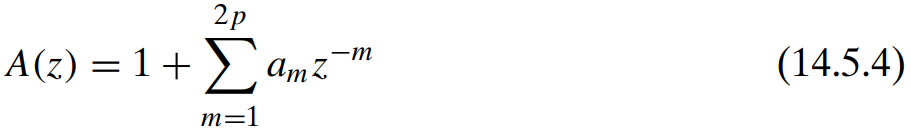

***Step 4*****:** Solve Eq. (14.5.11) for the signal powers $\left\lbrace P_i \right\rbrace$

        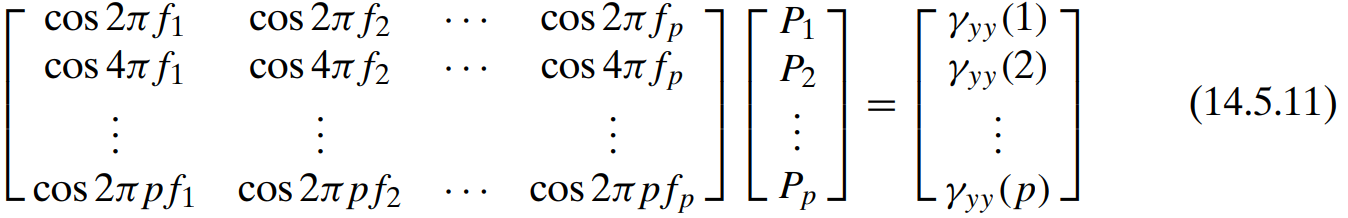

where 

- $\gamma_{\mathrm{yy}} \left(1\right),\gamma_{\mathrm{yy}} \left(2\right),\cdots ,\gamma_{\mathrm{yy}} \left(p\right)$ are the estimated autocorrelation values 

- $P_i =\frac{A_i^2 }{2}$ is the average power of the $i$th sinusoid and $A_i$ is the corresponding amplitude

***Step 5***: Estimate the amplitude $A_i =\sqrt{2P_i }$

These steps are coded up in the `pisarenko()` function (see at end of this document).

[F, A, P, lambda_min] = pisarenko(r_xx, 1)

F = 0.4393

A = 1.2955

P = 0.8391

lambda_min = 0.1609

We can describe the signal as:

        
$$x\left(n\right)=1\ldotp 2955\;\cos \left(2\pi \cdot 0\ldotp 4393n+\phi \right)+w\left(n\right)$$


where $w\left(n\right)$ is white noise with variance $\sigma_w^2 =0\ldotp 1609$

A sketch of the PSD in MATLAB:

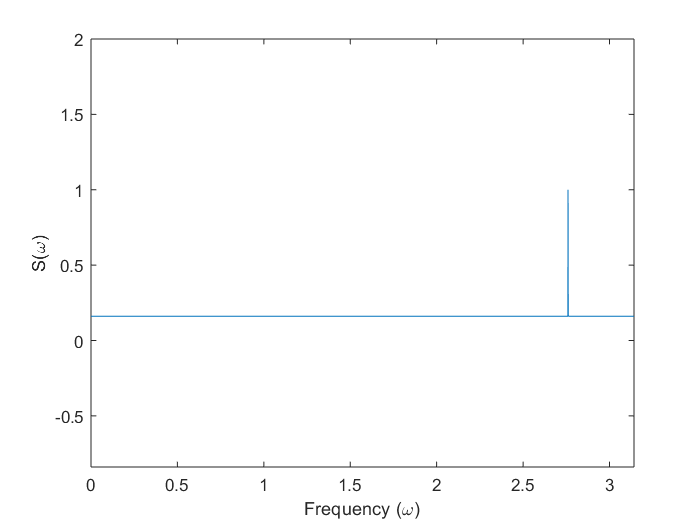

D = 3;
w = 0:10^-D:pi;
delta = @(n) round(n, D) == 0;
S = lambda_min*ones(1, numel(w)) + P*delta(w - 2*pi*F);
plot(w, S)
xlim([0, pi])
ylim([lambda_min-1, lambda_min+P+1])
xlabel('Frequency (\omega)')
ylabel('S(\omega)')

Since we have a formal description of the sinusoid, we can compute the power spectral density by finding the autocorrelation function of the sinusoid.

In ADSI Problem 4.4, we found that the autocorrelation of a real sinusoid given by $y\left(n\right)=A\;\mathrm{cos}\left(\omega n+\phi \right)$ where $A$ and $\omega$ are real constants and $\phi$ is a random variable with $\phi ~U\left(0,2\pi \right)$ is:

        
$$r_{\textrm{yy}} \left(\ell \right)=\frac{A^2 }{2}\mathrm{cos}\left(\omega \ell \right)$$


The autocorrelation function of white noise with variance $\sigma_w^2$ is given by:

        
$$r_{\mathrm{ww}} \left(\ell \right)=\sigma_w^2 \delta \left(\ell \right)$$


Combining these results, the general autocorrelation function of our signal is:

        
$$r_{\mathrm{xx}} \left(\ell \right)=\frac{A^2 }{2}\mathrm{cos}\left(\omega \ell \right)+\sigma_w^2 \delta \left(\ell \right)$$


The power spectral density is the Fourier transform the autocorrelation function which is given by:

        
$$S\left(\omega \right)=\frac{A^2 }{2}\pi \left\lbrack \delta \left(\omega -\omega_0 \right)+\delta \left(\omega +\omega_0 \right)\right\rbrack +\sigma_w^2$$


We can plot the PSD:

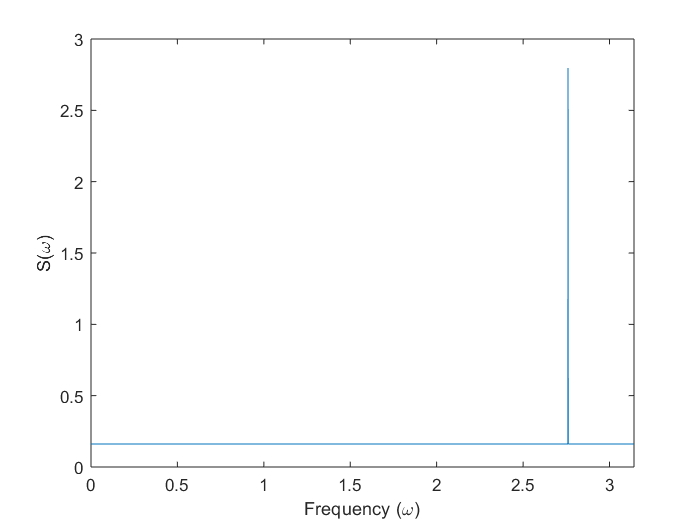

D = 3;
w = 0:10^(-D):pi;
delta = @(n) round(n, D) == 0;
S = (A^2/2)*pi * (delta(w-(F*2*pi)) + delta(w+(F*2*pi))) + lambda_min;
plot(w, S); 
xlabel('Frequency (\omega)');
ylabel('S(\omega)');
xlim([0, pi])

### 3) Comment on the appropriateness of the two models

Plotting the ACRS, we observe that it oscillates which indicates a high frequency signal.

The MA(2) model is basically a FIR filter with two coefficents and white noise as input where the Pisarenko model assumes that the signal is sinusoidal. 

Due to the oscillating nature of the ACRS, it is highly unlikely that the random signal is generated by a FIR filter. Therefore, the Pisarenko model is more appropriate in this model.

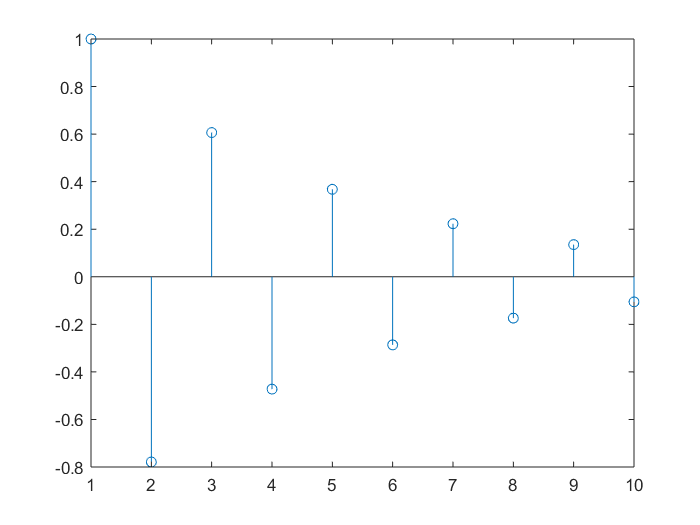

stem(r_xx)

## Problem 4

clear variables;

p = 3;
ell = 0:p-1;
r_vv = [3, 1, 0];

### 1) Calculate the signal to noise ratio in x(n)

The signal to noise ratio of the input signal is given by

        
$${\textrm{SNR}}_i =\frac{\textrm{power}\;\textrm{of}\;\textrm{signal}}{\textrm{power}\;\textrm{of}\;\textrm{noise}}=\frac{r_s \left(0\right)}{r_v \left(0\right)}$$


First, we need to find an analytical expression for the autocorrelation of $s\left(n\right)$. 

In ADSI Problem 4.4.1, we know that the autocorrelation of the complex sinusoid $z\left(n\right)={A\;e}^{j\left(\omega n+\phi \right)}$ where $A$ and $\omega$ are real constants and $\phi ~U\left(0,2\pi \right)$ is given by:

        
$$r_{\mathrm{zz}} \left(\ell \right)=A^2 \;e^{j\omega \ell } \;$$


Since the result from 4.4.1) uses Euler, we need to convert the signal to complex exponential. 

We use the relation $\mathrm{cos}\left(\theta \right)=\frac{1}{2}\left(e^{j\theta } +e^{-j\theta } \right)$

        
$$x\left(n\right)=A\;\mathrm{cos}\left(\omega \;n+\phi \right)$$


        
$$x\left(n\right)=\frac{A}{2}\;\left(e^{j\left(\omega n+\phi \right)} +e^{-j\left(\omega n+\phi \right)} \right)$$


        
$$x\left(n\right)=\frac{A}{2}e^{j\left(\omega n+\phi \right)} +\frac{A}{2}e^{-j\left(\omega n+\phi \right)}$$


Therefore, the autocorrelation of the real signal is:

        
$$r_{\mathrm{xx}} \left(\ell \right)={\left(\frac{A}{2}\right)}^2 e^{j\omega \ell } +{\left(\frac{A}{2}\right)}^2 e^{-j\omega \ell }$$


        
$$r_{\textrm{xx}} \left(\ell \right)=\frac{A^2 }{4}e^{j\omega \ell } +\frac{A^2 }{4}e^{-j\omega \ell }$$


        
$$r_{\textrm{xx}} \left(\ell \right)=\frac{A^2 }{4}\left(e^{j\omega \ell } +e^{-j\omega \ell } \right)$$


        
$$r_{\textrm{xx}} \left(\ell \right)=\frac{A^2 }{2}\frac{1}{2}\left(e^{j\omega \ell } +e^{-j\omega \ell } \right)$$


Using the relation $\cos \left(\theta \right)=\frac{1}{2}\left(e^{j\theta } +e^{-j\theta } \right)$  we can rewrite the autocorrelation to:

        
$$r_{\textrm{xx}} \left(\ell \right)=\frac{A^2 }{2}\mathrm{cos}\left(\omega \ell \right)$$


Thus, the autocorrelation function of a real signal $d\left(n\right)=A\;\cos \left(\omega n+\phi \right)$ where $A$ and $\omega$ are real constants and $\phi ~U\left(0,2\pi \right)$ is:

        
$$r_{\mathrm{dd}} \left(\ell \right)=\frac{A^2 }{2}\cos \left(\omega \ell \right)$$


In this problem, the autocorrelation of $s\left(n\right)$ is:

        
$$r_{\mathrm{ss}} \left(\ell \right)=2\mathrm{cos}\left(\frac{1}{4}\ell \right)$$


r_ss = 2.*cos(1/4.*ell)

r_ss =     2.0000    1.9378    1.7552


Now, we can calculate the SNR:

SNR_i = r_ss(1) / r_vv(1)

SNR_i = 0.6667

### 2) Solve the Wiener-Hopf equation

The $p$-order Wiener filter for estimating the signal $s\left(n\right)$ is given by:

        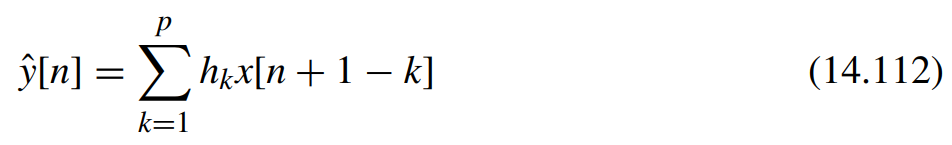

The optimum Wiener filter coefficients is given by the Wiener-Hopf equation:

        

where ${\mathit{\mathbf{R}}}_x$ is the autocorrelation matrix of the corrupted signal $s\left(n\right)$ and $\mathit{\mathbf{g}}$ is the cross-correlation between the desired signal $s\left(n\right)$ and the corrupted signal $x\left(n\right)$.

Designing a Wiener filter to recover a corrupted signal involves 3 steps:

- Compute the autocorrelation sequence $r_x \left(\ell \right)$ and matrix $R_x$

- Compute the cross-correlation $r_{\mathrm{sx}} \left(\ell \right)$

- Solve the Wiener-Hopf equation to find the optimum Wiener filter coefficients

**Step 1:** Compute $r_{\mathrm{xx}} \left(\ell \right)$

Since the signal $s\left(n\right)$ and the noise $v\left(n\right)$ are uncorrelated the autocorrelation function of $s\left(n\right)$ is just the sum of the individual autocorrelation functions:

      
$$r_{\mathrm{xx}} \left(\ell \right)=E\left\lbrack x\left(n\right)x\left(n-\ell \right)\right\rbrack$$


                 
$$=E\left\lbrack \left(s\left(n\right)+v\left(n\right)\right)\left(s\left(n-\ell \right)+v\left(n-\ell \right)\right)\right\rbrack$$


                 
$$=E\left\lbrack s\left(n\right)s\left(n-\ell \right)+s\left(n\right)v\left(n-\ell \right)+v\left(n\right)s\left(n-\ell \right)+v\left(n\right)v\left(n-\ell \right)\right\rbrack$$


                 
$$=r_{\mathrm{ss}} \left(\ell \right)+r_{\textrm{sv}} \left(\ell \right)+r_{\textrm{sv}} \left(\ell \right)+r_{\mathrm{vv}} \left(\ell \right)$$


                 
$$=r_{\textrm{ss}} \left(\ell \right)+r_{\textrm{vv}} \left(\ell \right)$$


r_xx = r_ss + r_vv

r_xx =     5.0000    2.9378    1.7552


R_xx = toeplitz(r_xx)

R_xx =     5.0000    2.9378    1.7552
    2.9378    5.0000    2.9378
    1.7552    2.9378    5.0000


**Step 2:** Compute the cross-correlation $r_{\mathrm{sx}} \left(\ell \right)$:

Since the desired signal is $y\left(n\right)=s\left(n\right)$ is uncorrelated with the noise $v\left(n\right)$, the cross-correlation between $s\left(n\right)$ and $v\left(n\right)$ simplifies to the autocorrelation of the signal $r_s \left(\ell \right)$.

        
$$r_{\textrm{yx}} \left(\ell \right)=E\left\lbrack y\left(n\right)x\left(n-\ell \right)\right\rbrack$$


                  
$$=E\left\lbrack s\left(n\right)\left(s\left(n-\ell \right)+v\left(n-\ell \right)\right)\right\rbrack$$


                  
$$=E\left\lbrack s\left(n\right)s\left(n-\ell \right)\right\rbrack +E\left\lbrack s\left(n\right)v\left(n-\ell \right)\right\rbrack$$


                  
$$=r_{\mathrm{ss}} \left(\ell \right)+r_{\textrm{sv}} \left(\ell \right)$$


                  $=r_{\mathrm{ss}} \left(\ell \right)+0$   (since $s\left(n\right)$ and $v\left(n\right)$ are uncorrelated $r_{\textrm{sv}} \left(\ell \right)=0$

g = r_ss'

g =     2.0000
    1.9378
    1.7552


**Step 3:** Compute the optimum filter coefficients:

h_opt = R_xx\g

h_opt =     0.2615
    0.1246
    0.1860


### 3) Compute the increase in MSE using another filter

The minimum value of the mean square error $E\left\lbrack e^2 \left(n\right)\right\rbrack =E\left\lbrack {\left(y\left(n\right)-\hat{y} \left(n\right)\right)}^2 \right\rbrack$ is given by  

        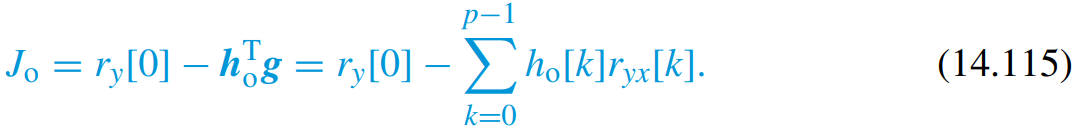

Let us compute it for the optimum 3-tap Wiener filter:

mse_opt = r_ss(1) - h_opt'*g

mse_opt = 0.9090

And the for other filter:

h_nonopt = [2, -1, 1]';
mse_nonopt = r_ss(1) - h_nonopt'*g

mse_nonopt = -1.8173

The difference is:

mse_opt - mse_nonopt

ans = 2.7264

## Problem 5

clear variables;

N = 3;
n = -N:N;
x = zeros(numel(n), 1);
g = zeros(numel(n), 1);
zero_point = ceil(numel(x)/2);
x(zero_point) = 2;
x(zero_point+1) = -1;

g(zero_point-1) = -1;
g(zero_point) = 3;
g(zero_point+1) = 1;

### 1) Upsample the signal x(n) by a factor of 3 and sketch the result

We can use MATLAB function to upsample the signal $x\left(n\right)$ by a factor of 3 using the given interpolation kernel $g\left(n\right)$:

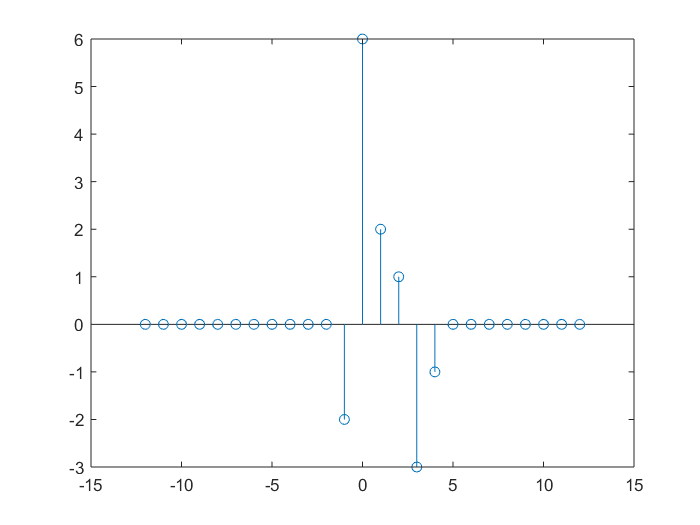

y = upfirdn(x, g, 3);
mid_y = ceil(numel(y)/2)-1;
n_y = -mid_y:mid_y;
stem(n_y, y)

### 2) Upsample the signal x(n) by a factor of 3 and compute the interpolated values

We use Eq. (12.33) to compute $x_I \left\lbrack 1\right\rbrack$ and  $x_I \left\lbrack 2\right\rbrack$ where $I=3$ is upsampling factor.

        

        
$$x_I \left\lbrack 1\right\rbrack =\sum_{m=0}^1 x\left\lbrack m\right\rbrack g\left\lbrack n-3m\right\rbrack =x\left\lbrack 0\right\rbrack g\left\lbrack 1\right\rbrack +x\left\lbrack 1\right\rbrack g\left\lbrack -2\right\rbrack =x\left\lbrack 0\right\rbrack g\left\lbrack 1\right\rbrack =2\cdot 1=2$$


        
$$x_I \left\lbrack 2\right\rbrack =\sum_{m=0}^1 x\left\lbrack m\right\rbrack g\left\lbrack n-3m\right\rbrack =x\left\lbrack 0\right\rbrack g\left\lbrack 2\right\rbrack +x\left\lbrack 1\right\rbrack g\left\lbrack -1\right\rbrack =0+\left(-1\right)\left(-1\right)=1$$


### 3) Discuss the performance of the interpolation kernel

The interpolation kernel seems to be poor because the interpolated signal does not look like the original signal. When interpolating, it can be expected that the kernel inserts $I-1$ samples between consecutive samples of $x\left(n\right)$. The given kernel adds modifies the signal.

## MATLAB Functions

function res = test()
    res = 1
end

function [k,G] = fir2lat(h)
% Converts FIR filter coefficients to lattice coefficients.
% From Figure 9.24 (p. 514)
    G = h(1); 
    a = h/G;
    M = length(h)-1; 
    k(M) = a(M+1);
    for m = M:-1:2
        b = fliplr(a);
        a = (a-k(m)*b)/(1-k(m)^2); a = a(1:m);
        k(m-1) = a(m);
    end
end


function [h] = lat2fir(k, G)
% Converts lattice coefficients to FIR filter coefficients.
% From Figure 9.25 (p. 515)
    a = 1; 
    b = 1; 
    M = length(k);
    for m = 1:1:M
        a = [a,0]+k(m)*[0,b];
        b = fliplr(a);
    end
    h = G*a;
end

function [F, A, P, lambda_min]=pisarenko(r_xx, p)
    % Estimates the frequencies and amplitudes using the Pisarenko method
    %  r_xx: autocorrelation sequence starting from zero. 
    %        The length of ACRS must be at least 2p+1.
    %  p: assumed number of sinusoids in the signal
    %  F: normalised frequencies of the sinuoids
    %  A: amplitudes of the sinuoids
    if numel(r_xx) < 2*p+1
        error(strcat('The length of ACRS must be at least ', int2str(2*p+1)));
    end
    
    % Compute the autocorrelation matrix
    R_xx = toeplitz(r_xx(1:2*p+1));
    
    % Perform the eigendecomposition
    [eigvecs, eigvals] = eigs(R_xx, size(R_xx, 1), 'smallestreal');
    
    eigvals = diag(eigvals);
    lambda_min = eigvals(1);
    
    % Find the eigenvector 'a' corresponding to the smallest eigenvalue.
    % The function eigs() sorts eigenvectors, so just pick the first column.
    a = eigvecs(:, 1);
    
    % Ensure that a_0 = 1 (this is by definition)
    a = a / a(1);
    
    % The elements of this eigenvector corresponds to the parameters
    % of an ARMA(2p, 2p) model: a_0, a_1, ..., a_2p where p: number of sinusoids
    % The polynomial A(z) in (14.5.4) has 2p poles on the unit circle.
    % Obtain the poles by finding the roots of the system.
    z = roots(a);
    
    % Estimate frequencies
    F = zeros(p, 1);
    for i = 1:p
        % The poles come in pairs. Each pair is complex conjugate
        % of one another. Only use one of them and find the absolute value.
        z_i = z(2*i);
        F(i) = abs(angle(z_i)) / (2*pi);
    end
    
    % Build the matrix of cosines
    C = zeros(p);
    for i = 1:p
        for j = 1:p
            C(i, j) = cos(i * 2*pi * F(j));
        end
    end
    
    % Start the ACRS from the second element according to equation (14.5.11)
    gamma = r_xx(2:p+1);
    
    % Solve equation (14.5.11) for P
    P = C\gamma; % Same as `inv(C)*gamma` but faster and more accurate
    
    % Since P=A^2/2, we can compute the amplitude A=sqrt(2*P)
    A = sqrt(2 * P);
end